close all;
clear all;

clock_freq = 1e8;

limits = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 18, 20, 24, 28, 35, 45, 60, 75, 100, 125, 150, 175, 200];
time = limits.*(1e6/clock_freq);
n_cells = 64;

model = "basys";

## TERO cell (4-LUT)

prefix="tero_4";
tero_4_cells_averages = zeros(n_cells, length(limits));

for i=1:length(limits)
    data = readmatrix(model+"_"+prefix+'_count_limit_'+string(limits(i))+'.csv');
    for j=1:n_cells
        tero_4_cells_averages(j,i) = mean(data(:,j));
    end
end

### Average cells oscillations

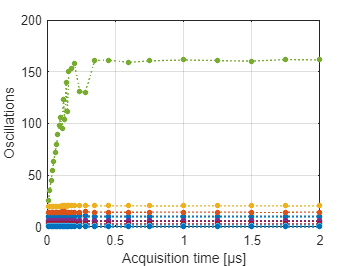

fig_tero_4_avr = figure;
for i=1:n_cells
    p = plot(time, tero_4_cells_averages(i,:), ':.');hold on;
    p.MarkerSize = 12;
end
ylabel("Oscillations");
xlabel("Acquisition time [µs]");
grid on;

### Average cells oscillations (zoomed)

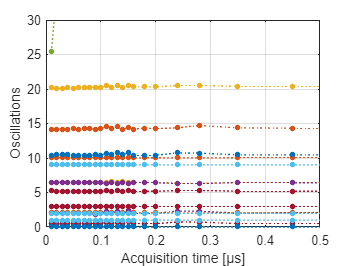

fig_tero_4_avr_zoomed = figure;
for i=1:n_cells
    p = plot(time, tero_4_cells_averages(i,:), ':.');hold on;
    p.MarkerSize = 12;
end
ylabel("Oscillations");
xlabel("Acquisition time [µs]");
xlim([0 0.5]);
ylim([0 30]);
grid on;

### Final state

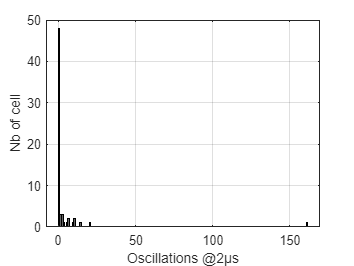

fig_tero_4_final = figure;
h = histogram(tero_4_cells_averages(:,length(limits)), ceil(max(tero_4_cells_averages(:,length(limits)))));
h.FaceColor = 'black';
h.EdgeColor = 'black';
xlabel("Oscillations @2µs");
ylabel("Nb of cell");
grid on;

## TERO cell (8-LUT)

prefix="tero_8";
tero_8_cells_averages = zeros(n_cells, length(limits));

for i=1:length(limits)
    data = readmatrix(model+"_"+prefix+'_count_limit_'+string(limits(i))+'.csv');
    for j=1:n_cells
        tero_8_cells_averages(j,i) = mean(data(:,j));
    end
end

### Average cells oscillations

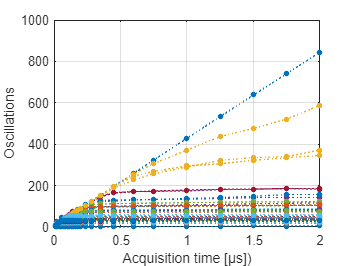

fig_tero_8_avr = figure;
for i=1:n_cells
    p = plot(time, tero_8_cells_averages(i,:), ':.');hold on;
    p.MarkerSize = 12;
end
ylabel("Oscillations");
xlabel("Acquisition time [µs])");
grid on;

### Average cells oscillations (zoomed)

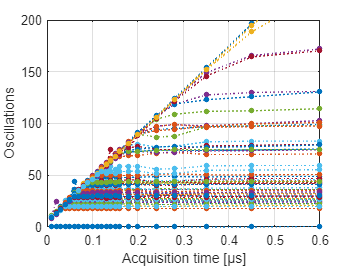

fig_tero_8_avr_zoomed = figure;
for i=1:n_cells
    p = plot(time, tero_8_cells_averages(i,:), ':.');hold on;
    p.MarkerSize = 12;
end
ylabel("Oscillations");
xlabel("Acquisition time [µs]");
xlim([0 0.6]);
ylim([0 200]);
grid on;

### Final state

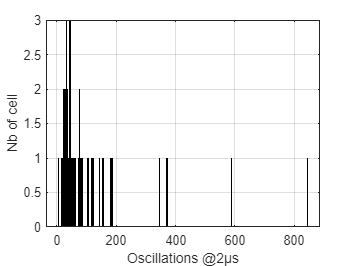

fig_tero_8_final = figure;
h = histogram(tero_8_cells_averages(:,length(limits)), ceil(max(tero_8_cells_averages(:,length(limits)))));
h.FaceColor = 'black';
h.EdgeColor = 'black';
xlabel("Oscillations @2µs");
ylabel("Nb of cell");
grid on;

## TERO cell (4-LUT) unlocked

prefix="tero_4";
tero_4_cells_unlocked_averages = zeros(n_cells, length(limits));

for i=1:length(limits)
    data = readmatrix(model+"_unlocked_"+prefix+'_count_limit_'+string(limits(i))+'.csv');
    for j=1:n_cells
        tero_4_cells_unlocked_averages(j,i) = mean(data(:,j));
    end
end

### Average cells oscillations

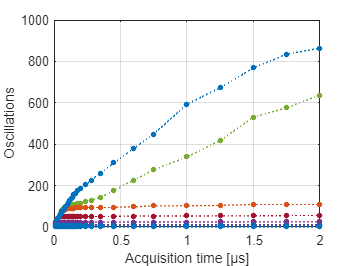

fig_tero_4_unlocked_avr = figure;
for i=1:n_cells
    p = plot(time, tero_4_cells_unlocked_averages(i,:), ':.');hold on;
    p.MarkerSize = 12;
end
ylabel("Oscillations");
xlabel("Acquisition time [µs]");
grid on;

### Average cells oscillations (zoomed)

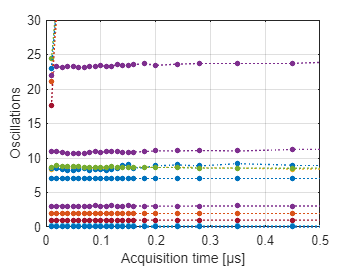

fig_tero_4_unlocked_avr_zoomed = figure;
for i=1:n_cells
    p = plot(time, tero_4_cells_unlocked_averages(i,:), ':.');hold on;
    p.MarkerSize = 12;
end
ylabel("Oscillations");
xlabel("Acquisition time [µs]");
xlim([0 0.5]);
ylim([0 30]);
grid on;

### Final state

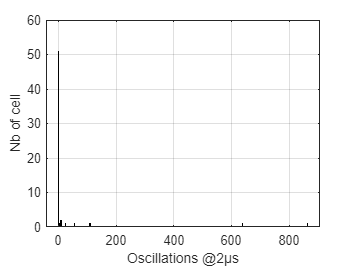

fig_tero_4_unlocked_final = figure;
h = histogram(tero_4_cells_unlocked_averages(:,length(limits)), ceil(max(tero_4_cells_unlocked_averages(:,length(limits)))));
h.FaceColor = 'black';
h.EdgeColor = 'black';
xlabel("Oscillations @2µs");
ylabel("Nb of cell");
grid on;

## TERO cell (8-LUT) unlocked

prefix="tero_8";
tero_8_cells_unlocked_averages = zeros(n_cells, length(limits));

for i=1:length(limits)
    data = readmatrix(model+"_unlocked_"+prefix+'_count_limit_'+string(limits(i))+'.csv');
    for j=1:n_cells
        tero_8_cells_unlocked_averages(j,i) = mean(data(:,j));
    end
end

### Average cells oscillations

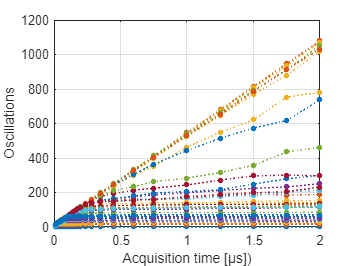

fig_tero_8_unlocked_avr = figure;
for i=1:n_cells
    p = plot(time, tero_8_cells_unlocked_averages(i,:), ':.');hold on;
    p.MarkerSize = 12;
end
ylabel("Oscillations");
xlabel("Acquisition time [µs])");
grid on;

### Average cells oscillations (zoomed)

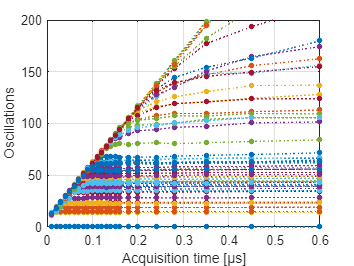

fig_tero_8_unlocked_avr_zoomed = figure;
for i=1:n_cells
    p = plot(time, tero_8_cells_unlocked_averages(i,:), ':.');hold on;
    p.MarkerSize = 12;
end
ylabel("Oscillations");
xlabel("Acquisition time [µs]");
xlim([0 0.6]);
ylim([0 200]);
grid on;

### Final state

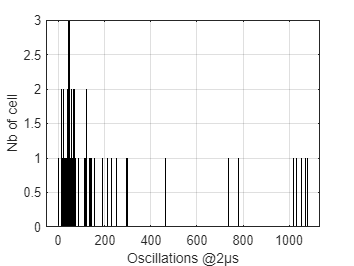

fig_tero_8_unlocked_final = figure;
h = histogram(tero_8_cells_unlocked_averages(:,length(limits)), ceil(max(tero_8_cells_unlocked_averages(:,length(limits)))));
h.FaceColor = 'black';
h.EdgeColor = 'black';
xlabel("Oscillations @2µs");
ylabel("Nb of cell");
grid on;

saveas(fig_tero_4_avr, "tero_4_oscillations_vs_time.png");

saveas(fig_tero_4_avr_zoomed, "tero_4_oscillations_vs_time_zoomed.png");

saveas(fig_tero_4_final, "tero_4_oscillations_final.png");

saveas(fig_tero_8_avr, "tero_8_oscillations_vs_time.png");

saveas(fig_tero_8_avr_zoomed, "tero_8_oscillations_vs_time_zoomed.png");

saveas(fig_tero_8_final, "tero_8_oscillations_final.png");

saveas(fig_tero_4_unlocked_avr, "tero_4_unlocked_oscillations_vs_time.png");

saveas(fig_tero_4_unlocked_avr_zoomed, "tero_4_unlocked_oscillations_vs_time_zoomed.png");

saveas(fig_tero_4_unlocked_final, "tero_4_unlocked_oscillations_final.png");

saveas(fig_tero_8_unlocked_avr, "tero_8_unlocked_oscillations_vs_time.png");

saveas(fig_tero_8_unlocked_avr_zoomed, "tero_8_unlocked_oscillations_vs_time_zoomed.png");

saveas(fig_tero_8_unlocked_final, "tero_4_unlocked_oscillations_final.png");